# Separación de minerales mediante cargas

clear; clc;

## Parámetros

Los parámetros que utilizaremos para graficar la separación de minelares serían las cargas que presentan, el campo eléctrico presente, la masa de las cargas y la fuerza de gravedad.

q = 9e-6; % micro C/m
E = 500e+3; % kv/m
m=1; 
g=-9.81; 

## Creación de elementos

A continuación, creé una serie de objetos con posición X y Y y que cuenten con un dato random para poder separarlos entre positivos y negativos. Al igual que calcular el valor de la aceleración para cada carga y crear una matriz para la velocidad empezando en 0s. 


%condiciones iniciales 
x0 = zeros(100, 3);
for i = 1:100
    x0(i, 1) = randi(25) + 35;
    x0(i, 2) = 10;
    x0(i, 3) = randi(2);
end
v0 = zeros(100, 3);

ax1 = q*E;
ax2 = -q*E;

x = 1:100;

## Ciclo

Para la graficación se utilizan dos ciclos, uno para determinar la posición de las partículas a travez del tiempo, y otro para actualizar los datos de todas las partículas en cada repetición. Este ciclo termina generando una animación de las partículas siendo separadas a ambos extremos.

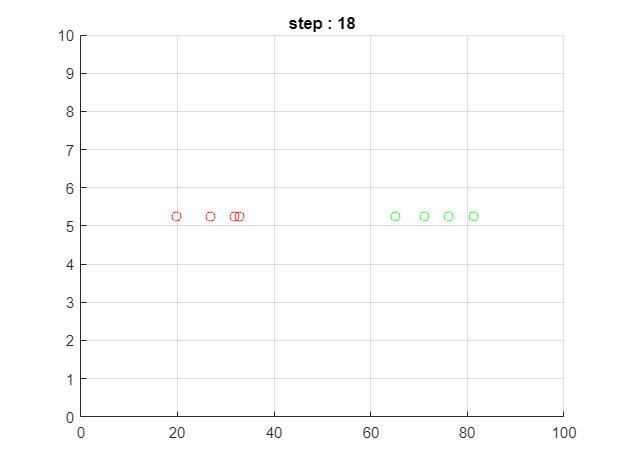

for step=1:1000  
    grid on
    hold on
    
    for i = 1:10
        va = v0;
        if(x0(i, 3) == 1)
            plot(x0(i, 1), x0(i, 2), "og");
            v0(i, 1) = va(i, 1) + 1/2 * ax1 * step/30^2;
        else
            plot(x0(i, 1), x0(i, 2), "or");
            v0(i, 1) = va(i, 1) + 1/2 * ax2 * step/30^2;
        end 
        xa = x0; 
        v0(i, 2) = va(i, 2) + 1/2 * g * step/100^2;
        if x0(1) > 20 && x0(1) < 80
            x0= xa + v0;
        end
    end
    hold off

    title(['step : ' num2str(step)]); 
    axis([0 100 0 10]); 
    pause(0.01);
    
    if x0(1) < 20 || x0(1) > 80
        break
    end
    
    
    clf;
end

## Gráficas de velocidad y aceleración.

Estos son ejemplos de cómo se comportaría la velocidad y aceleración en el experimento propuesto en función del tiempo en un lapso de 100 segundos. 

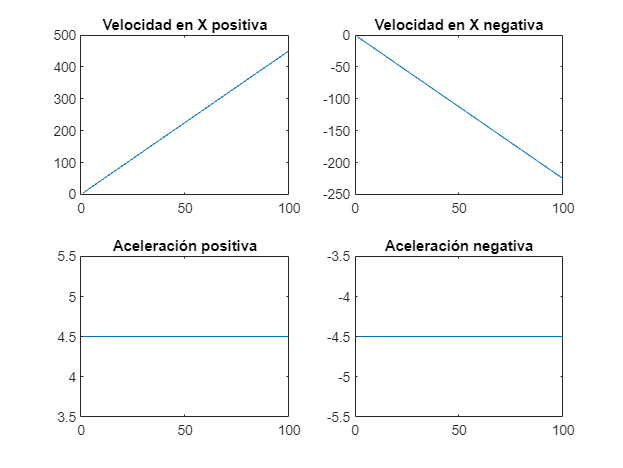


subplot(2, 2, 1);
v=0;
v = v + ax1.*x;
plot(x, v(x))
title("Velocidad en X positiva")

subplot(2, 2, 2);
v=0;
v = @(x) v + 1/2 * ax2.*x;
plot(x, v(x))
title("Velocidad en X negativa")

subplot(2, 2, 3);
ax1 = ones(size(x)) * ax1;
plot(x, ax1);
title("Aceleración positiva");

subplot(2, 2, 4);
ax2 = ones(size(x)) * ax2;
plot(x, ax2);
title("Aceleración negativa");